# **Script per la creazione delle strutture dati per il progetto di Reti di Telecomunicazione in IBM OPL CPLEX**

## RENATER

### `Rete nazionale francese per la tecnologia, la ricerca e l'istruzione `

#### Specifiche tecniche*

Capacità dei canali [Mbit/s]:

- capacità di un canale di trasferimento all'interno della backbone: 155;

- capacità di un canale di uscita dalla backbone: 200.

Costi di attraversamento [unità di costo/(Mbit/s)]:

- costo di percorrenza di un canale di *accesso* alla backbone: [25, 30]; 

- costo di percorrenza di un canale di *trasferimento* all'interno della backbone: [15, 20];

- costo di percorrenza di un *uscita* dalla backbone: [5, 10].

Specifiche dei router:

- capacità [Mbit/s]: [175, 200];

- costo di installazione [unità di costo]: [5000, 7600].

Traffici [Mbit/s]: [15, 70].

*gli intervalli sono stati scelti dallo studente.

NB: le istruzioni di esportazione dei dati in formato .xls sono state *commentate* poiché, nonostante il seme del generatore di numeri causali sia impostato a 1 e la ripetitività dei numeri aleatori sia quindi garantita, non si vuole comunque rischiare di generare dei file contenenti dei dati diversi da quelli che sono stati utilizzati per provare il modello di ottimizzazione e per scrivere la relazione. 

#### Importazione dei dati, parsing GML e identificazione dei siti candidati CSs (Candidate Sites) e dei canali di trasferimento TRASFs (TRASFers)

clear all
clc
rng(1)

FRA = fileread("RENATER_2010.gml");
string_N = 'node.*?id (?<Id>\d+).*?label\s*"(?<Label>[^"]*)"';
string_A = 'edge.*?source\s*(?<Source>\d+).*?target\s*(?<Target>\d+).*?LinkSpeed\s*"(?<LinkSpeed>[^"]*)"';

N_FRA = struct2table(regexp(FRA, string_N, 'names'));
N_FRA.Properties.VariableNames = ["ID", "Nome"];
A_FRA = struct2table(regexp(FRA, string_A, 'names'));
A_FRA.Properties.VariableNames = ["Sorgente", "Destinazione", "Capacita"];

#### Creazione ed esportazione della tabella contenente le informazioni relative ai router installati presso i CSs, ai TPs e ai DNs

cat_nodo = string(num2str(zeros(size(N_FRA,1),1)));
N_FRA = addvars(N_FRA, cat_nodo);
cap_nodo = zeros(size(N_FRA,1),1);
N_FRA = addvars(N_FRA, cap_nodo);
costo_nodo = zeros(size(N_FRA,1),1);
N_FRA = addvars(N_FRA, costo_nodo);
N_FRA.Properties.VariableNames = ["ID", "Nome", "Categoria", "Capacita", "CostoInst"];
N_FRA.ID = string(N_FRA.ID);
N_FRA.Nome = string(N_FRA.Nome);
for i=1:size(N_FRA,1)
    N_FRA.Categoria(i) = "CS";
    N_FRA.Capacita(i) = floor(175 + 26*rand());
    N_FRA.CostoInst(i) = floor(5000 + 2600*rand());
end

Creazione dei TPs

k = 1;
for i = 50:55
    N_FRA = [N_FRA; {num2str(i), strcat("Client",num2str(k)), "TP", 0, 0}];
    k = k+1;
end

Creazione dei DNs ed esportazione dei dati relativi ai nodi

k = 1;
for i = 60:65
    N_FRA = [N_FRA; {num2str(i), strcat("Server",num2str(k)), "DN", 0, 0}];
    k = k+1;
end

% writetable(N_FRA, 'Modello OPL\N_RENATER.xls')

#### Creazione della tabella contenente le informazioni relative ai canali di accesso INs, di uscita OUTs e di trasferimento TRASFs

id_arco = string(num2str(zeros(size(A_FRA,1),1)));
A_FRA = addvars(A_FRA, id_arco, 'Before', 'Sorgente');
cat_arco = string(num2str(zeros(size(A_FRA,1),1)));
A_FRA = addvars(A_FRA, cat_arco, 'After', 'id_arco');
tecn_arco = string(num2str(zeros(size(A_FRA,1),1)));
A_FRA = addvars(A_FRA, tecn_arco, 'After', 'cat_arco');
A_FRA.Capacita = zeros(size(A_FRA,1),1);
costoAttr_arco = zeros(size(A_FRA,1),1);
A_FRA = addvars(A_FRA, costoAttr_arco);
A_FRA.Properties.VariableNames = ["ID", "Categoria", "Tecnologia", "Sorgente",...
    "Destinazione", "Capacita", "CostoAttr"];
A_FRA.Sorgente = string(A_FRA.Sorgente);
A_FRA.Destinazione = string(A_FRA.Destinazione);
for i = 1:size(A_FRA,1)
    A_FRA.Categoria(i) = "TRASF-DIR";
    A_FRA.Tecnologia(i) = "Cavo";
    A_FRA.Capacita(i) = 155;
    A_FRA.CostoAttr(i) = floor(15 + 6*rand());
end


Creazione dei canali di trasferimento inversi

k = 57;
for i=1:56
    A_FRA = [A_FRA; {" ", "TRASF-INV", "Cavo", A_FRA{i,"Destinazione"},...
        num2str(A_FRA{i,"Sorgente"}), 155, A_FRA{i,"CostoAttr"}}];
    k = k+1;
end

Creazione dei canali di accesso alla backbone

M_Input = [0,18; 6,28; 8,9; 35,37; 14,29; 10,41];
for i=1:6
    for k=1:2
        A_FRA = [A_FRA; {" ", "IN", "Wireless",...
            num2str(49+i), num2str(M_Input(i,k)),...
            0, floor(25 + 6*rand())}];
    end
end

Creazione dei canali di uscita dalla backbone ed esportazione dei dati relativi agli archi

M_Output = [33; 25; 5; 24; 42; 17];
for i=1:6
    A_FRA = [A_FRA; {" ", "OUT", "Wireless",...
    num2str(M_Output(i,1)), num2str(59+i),...
    200, floor(5 + 6*rand())}];
end

for i=1:size(A_FRA,1)
    A_FRA.ID(i) = string(strcat(strcat(A_FRA.Sorgente{i},'-'), A_FRA.Destinazione{i}));
end

% writetable(A_FRA, 'Modello OPL\A_RENATER.xls')

#### Rappresentazione grafica di RENATER senza TPs e DNs

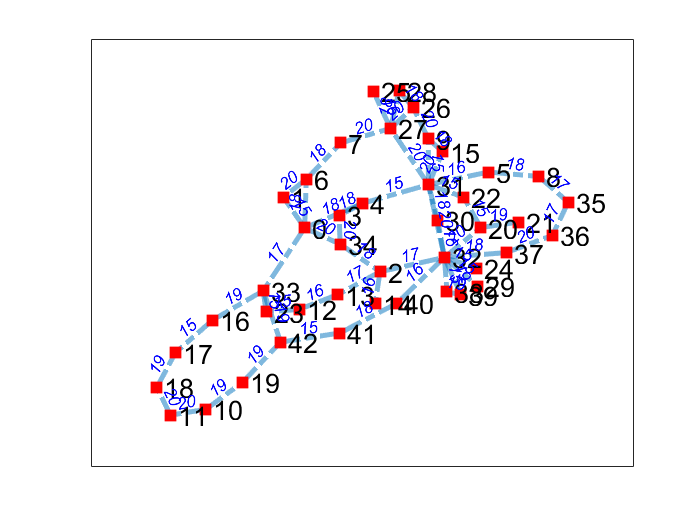

G1_FRA = graph(A_FRA{1:56,"Sorgente"}, A_FRA{1:56,"Destinazione"},...
    A_FRA{1:56,"CostoAttr"});
h1 = plot(G1_FRA, 'EdgeLabel', G1_FRA.Edges.Weight);
h1.NodeColor = "r";
h1.Marker = "s";
h1.MarkerSize = 8;
h1.NodeFontSize = 16;
h1.LineWidth = 3;
h1.EdgeFontSize = 10;
h1.EdgeLabelColor = "blue";
h1.LineStyle = "-.";
box on

#### Creazione ed esportazione delle matrici dei traffici dai TPs ai DNs

k = numero di traffici = 2

TPs = N_FRA{strcmp(N_FRA.Categoria, "TP"),"ID"};
DNs = N_FRA{strcmp(N_FRA.Categoria, "DN"),"ID"};
K_FRA = table('RowNames', TPs);
for i = 1:size(DNs,1)
    K_FRA = addvars(K_FRA, zeros(size(TPs,1),1));
end
K_FRA.Properties.VariableNames = DNs';

K_FRA("50","62") = {108};
K_FRA("55","62") = {57};

writetable(K_FRA, 'Modello OPL\K_RENATER_2.xls')

k = 5

TPs = N_FRA{strcmp(N_FRA.Categoria, "TP"),"ID"};
DNs = N_FRA{strcmp(N_FRA.Categoria, "DN"),"ID"};
K_FRA = table('RowNames', TPs);
for i = 1:size(DNs,1)
    K_FRA = addvars(K_FRA, zeros(size(TPs,1),1));
end
K_FRA.Properties.VariableNames = DNs';

K_FRA("50","62") = {108};
K_FRA("55","62") = {57};
K_FRA("53","61") = {41};
K_FRA("54","61") = {46};
K_FRA("51","64") = {39};

writetable(K_FRA, 'Modello OPL\K_RENATER_5.xls')

k = 10

TPs = N_FRA{strcmp(N_FRA.Categoria, "TP"),"ID"};
DNs = N_FRA{strcmp(N_FRA.Categoria, "DN"),"ID"};
K_FRA = table('RowNames', TPs);
for i = 1:size(DNs,1)
    K_FRA = addvars(K_FRA, zeros(size(TPs,1),1));
end
K_FRA.Properties.VariableNames = DNs';

K_FRA("50","62") = {108};
K_FRA("55","62") = {57};
K_FRA("53","61") = {41};
K_FRA("54","61") = {46};
K_FRA("51","64") = {39};
K_FRA("52","63") = {61};
K_FRA("52","60") = {64};
K_FRA("50","65") = {53};
K_FRA("51","60") = {22};
K_FRA("55","63") = {49};

writetable(K_FRA, 'Modello OPL\K_RENATER_10.xls')

k = 15

TPs = N_FRA{strcmp(N_FRA.Categoria, "TP"),"ID"};
DNs = N_FRA{strcmp(N_FRA.Categoria, "DN"),"ID"};
K_FRA = table('RowNames', TPs);
for i = 1:size(DNs,1)
    K_FRA = addvars(K_FRA, zeros(size(TPs,1),1));
end
K_FRA.Properties.VariableNames = DNs';

K_FRA("50","62") = {108};
K_FRA("55","62") = {57};
K_FRA("53","61") = {41};
K_FRA("54","61") = {46};
K_FRA("51","64") = {39};
K_FRA("52","63") = {61};
K_FRA("52","60") = {64};
K_FRA("50","65") = {53};
K_FRA("51","60") = {22};
K_FRA("55","63") = {49};
K_FRA("53","64") = {58};
K_FRA("54","65") = {50};
K_FRA("55","60") = {39};
K_FRA("53","62") = {11};
K_FRA("50","63") = {23};

writetable(K_FRA, 'Modello OPL\K_RENATER_15.xls')

k = 20

TPs = N_FRA{strcmp(N_FRA.Categoria, "TP"),"ID"};
DNs = N_FRA{strcmp(N_FRA.Categoria, "DN"),"ID"};
K_FRA = table('RowNames', TPs);
for i = 1:size(DNs,1)
    K_FRA = addvars(K_FRA, zeros(size(TPs,1),1));
end
K_FRA.Properties.VariableNames = DNs';

K_FRA("50","62") = {108};
K_FRA("55","62") = {57};
K_FRA("53","61") = {41};
K_FRA("54","61") = {46};
K_FRA("51","64") = {39};
K_FRA("52","63") = {61};
K_FRA("52","60") = {64};
K_FRA("50","65") = {53};
K_FRA("51","60") = {22};
K_FRA("55","63") = {49};
K_FRA("53","64") = {58};
K_FRA("54","65") = {50};
K_FRA("55","60") = {39};
K_FRA("53","62") = {11};
K_FRA("50","63") = {23};
K_FRA("54","62") = {12}; 
K_FRA("52","65") = {15}; 
K_FRA("51","61") = {38}; 
K_FRA("55","65") = {18}; 
K_FRA("53","60") = {44}; 

writetable(K_FRA, 'Modello OPL\K_RENATER_20.xls')

#### Elaborazione dei risultati

Righe = ["k2_SPLIT", "k2_UNSPLIT", "k5_SPLIT", "k5_UNSPLIT", "k10_SPLIT",...
    "k10_UNSPLIT", "k15_SPLIT", "k15_UNSPLIT", "k20_SPLIT", "k20_UNSPLIT"];
Colonne = ["UtilizzoMedioCanaliAttivi", "UtilizzoBackbone", "NumMedioCanaliPerTraffico",...
    "NumRuoterAttivi"];
Risultati = table('RowNames', Righe);
for i=1:size(Colonne,2)
    Risultati = addvars(Risultati, zeros(size(Risultati,1),1));
end
Risultati.Properties.VariableNames = Colonne;
Num_traffici = [0,0,2,0,0,0,1;0,0,2,0,0,0,1;0,2,2,0,1,0,3;0,2,2,0,1,0,3;2,2,2,2,1,1,6;2,2,2,2,1,1,6;...
    3,2,3,3,2,2,6;3,2,3,3,2,2,6;4,3,4,3,2,4,6;4,3,4,3,2,4,6];

for k=1:size(Righe,2)
    T1 = readtable("Modello OPL\Risultati.xlsx", "Sheet", Righe(k), "Range",...
        'A1:F112');
    T2 = readtable("Modello OPL\Risultati.xlsx", "Sheet", Righe(k), "Range",...
        'A115:A157');
    sommaTot = 0;
    cont = 0;
    for i=1:size(T1,1)
        sommaPar = 0;
        for j=1:size(T1,2)
            sommaPar = sommaPar + T1{i,j};
        end
        if sommaPar > 0.5
            sommaTot = sommaTot + sommaPar;
            cont = cont + 1;
        end
    end
    sommaTot2 = 0;
    for j=1:size(T1,2)
        sommaPar2 = 0;
        for i=1:size(T1,1)
            if T1{i,j} > 0.5
                sommaPar2 = sommaPar2 + 1;
            end
        end
        if Num_traffici(k,j) ~= 0
            sommaTot2 = sommaTot2 + sommaPar2/Num_traffici(k,j);
        end
    end
    Risultati(k, "UtilizzoMedioCanaliAttivi") = {round(((sommaTot/155)/cont)*100,2)};
    Risultati(k, "UtilizzoBackbone") = {round(((sommaTot/155)/112)*100,2)};
    Risultati(k, "NumRuoterAttivi") = {sum(T2{:,1},1)};
    Risultati(k, "NumMedioCanaliPerTraffico") = {round(sommaTot2/Num_traffici(k,7),2)}; % da rivedere
end

#### Rappresentazione grafica della RENATER con i traffci, k = 2, con e senza spitting

Grafo con splitting del traffico

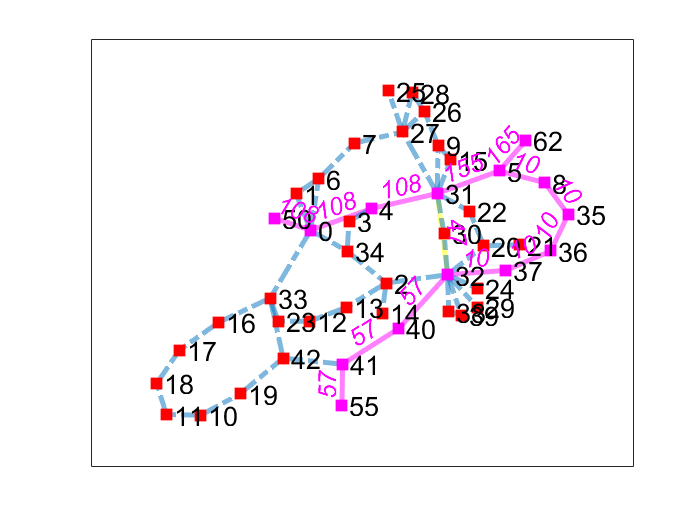

G2_FRA = addedge(G1_FRA, "50", "0", NaN);
G2_FRA = addedge(G2_FRA, "55", "41", NaN);
G2_FRA = addedge(G2_FRA, "5", "62", NaN);
h2 = plot(G2_FRA);
camroll(180)
h2.NodeColor = "r";
h2.Marker = "s";
h2.MarkerSize = 8;
h2.NodeFontSize = 16;
h2.LineWidth = 3;
h2.LineStyle = "-.";
box on
P1_SPLIT = ["50", "0", "4", "31", "5", "62"];
L1_SPLIT = {'108' '108' '108' '155' '165'};
P2_SPLIT = ["55", "41", "40", "32", "37", "36", "37", "36", "35", "8", "5"];
L2_SPLIT = {'57', '57', '57', '10', '10', '10', '10', '10'};
P3_SPLIT = ["32", "31"];
L3_SPLIT = {'47'};
highlight(h2, P1_SPLIT, "EdgeColor", '#FF00FF', "LineStyle", "-")
highlight(h2, P1_SPLIT, "NodeColor", '#FF00FF')
highlight(h2, P2_SPLIT, "EdgeColor", '#FF00FF', "LineStyle", "-")
highlight(h2, P2_SPLIT, "NodeColor", '#FF00FF')
highlight(h2, P3_SPLIT, "EdgeColor", '#FFFF00', "LineStyle", "-")
labeledge(h2, {'50' '0' '4' '31' '5'}, {'0' '4' '31' '5' '62'},...
    L1_SPLIT)
labeledge(h2, {'55' '41' '40' '32' '37' '36' '35' '8'}, {'41' '40' '32' '37' '36' '35' '8' '5'},...
    L2_SPLIT)
labeledge(h2, '32', '31', L3_SPLIT)
h2.EdgeFontSize = 15;
h2.EdgeLabelColor = '#FF00FF';

Grafo senza splitting del traffico

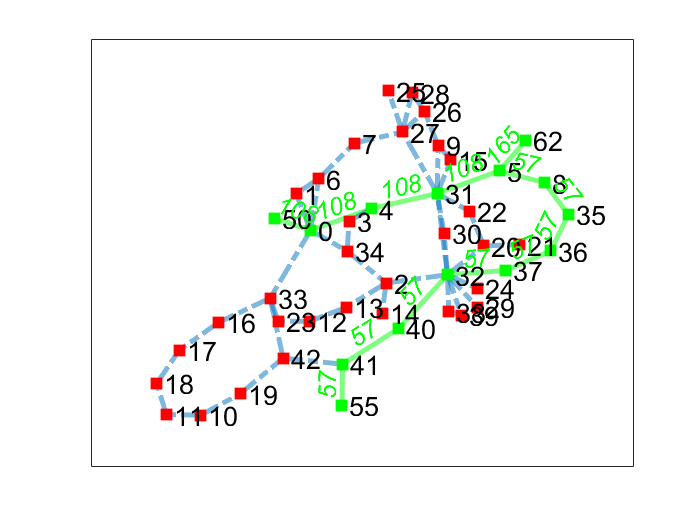

h3 = plot(G2_FRA);
camroll(180)
h3.NodeColor = "r";
h3.Marker = "s";
h3.MarkerSize = 8;
h3.NodeFontSize = 16;
h3.LineWidth = 3;
h3.LineStyle = "-.";
box on
P1_UNSPLIT = ["50", "0", "4", "31", "5", "62"];
L1_UNSPLIT = {'108' '108' '108' '108' '165'};
P2_UNSPLIT = ["55", "41", "40", "32", "37", "36", "37", "36", "35", "8", "5"];
L2_UNSPLIT = {'57', '57', '57', '57', '57', '57', '57', '57'};
highlight(h3, P1_UNSPLIT, "EdgeColor", 'green', "LineStyle", "-")
highlight(h3, P1_UNSPLIT, "NodeColor", 'green')
highlight(h3, P2_UNSPLIT, "EdgeColor", 'green', "LineStyle", "-")
highlight(h3, P2_UNSPLIT, "NodeColor", 'green')
labeledge(h3, {'50' '0' '4' '31' '5'}, {'0' '4' '31' '5' '62'},...
    L1_UNSPLIT)
labeledge(h3, {'55' '41' '40' '32' '37' '36' '35' '8'}, {'41' '40' '32' '37' '36' '35' '8' '5'},...
    L2_UNSPLIT)
h3.EdgeFontSize = 15;
h3.EdgeLabelColor = 'green';